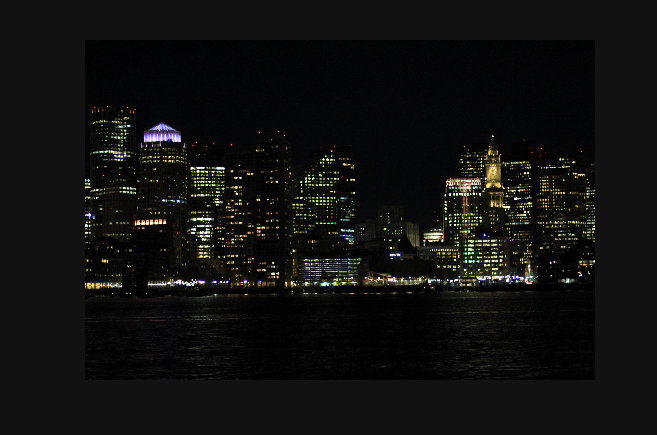

clc, clearvars;
img = imread("boston night.jpg");
imshow(img);

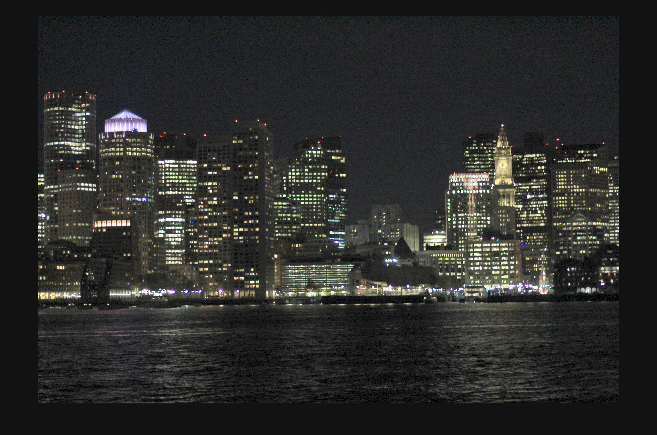

% Gamma correction
gamma = 1/2;
imgDouble = im2double(img);
imgGamma = imgDouble .^ gamma;
imshow(imgGamma);

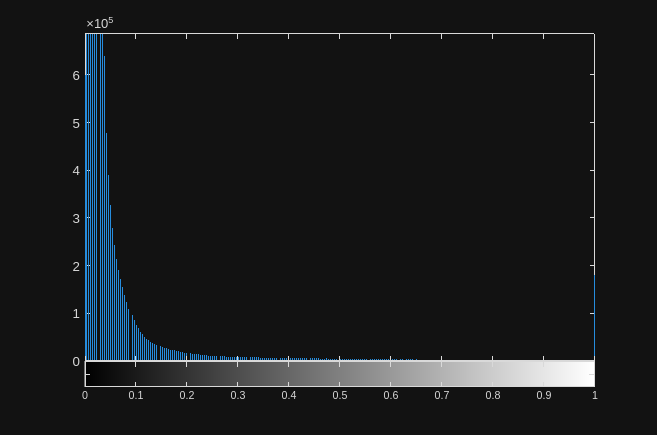

% Adjusted image
imgHSV = rgb2hsv(img);
val = imgHSV(:, :, 3);
val = imadjust(val);
imhist(val);

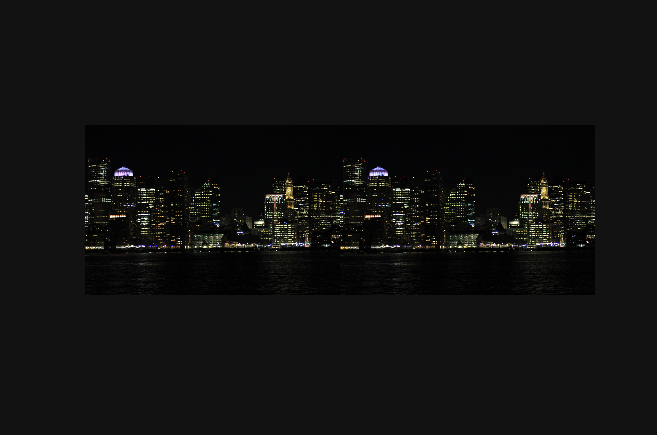

imgHSV(:, :, 3) = val;
imgAdjusted = im2uint8(hsv2rgb(imgHSV));
montage({img, imgAdjusted});

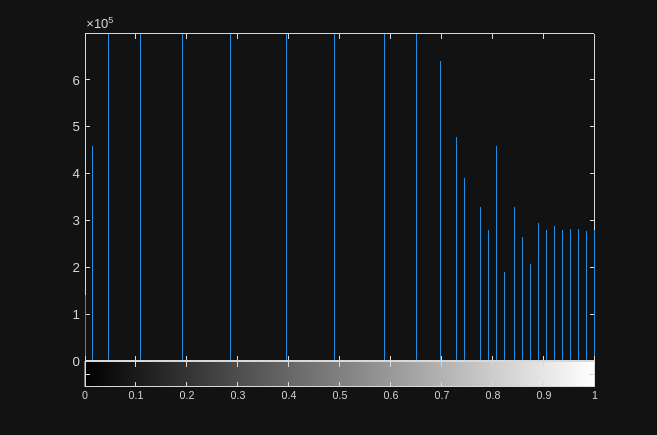

% Histogram equalization
imgHSV = rgb2hsv(img);
val = imgHSV(:, :, 3);
val = histeq(val);
imhist(val);

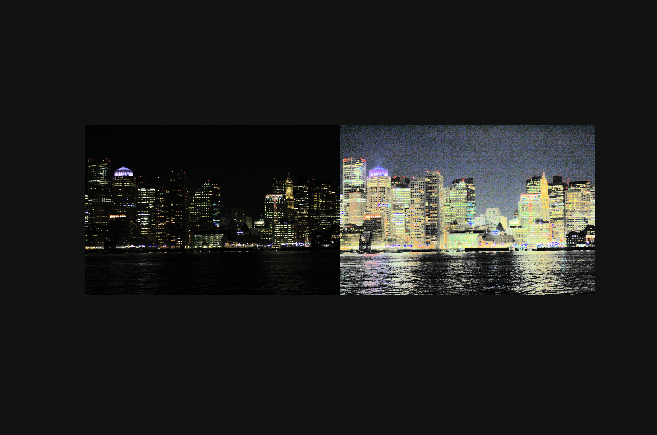

imgHSV(:, :, 3) = val;
imgEqualized = im2uint8(hsv2rgb(imgHSV));
montage({img, imgEqualized});

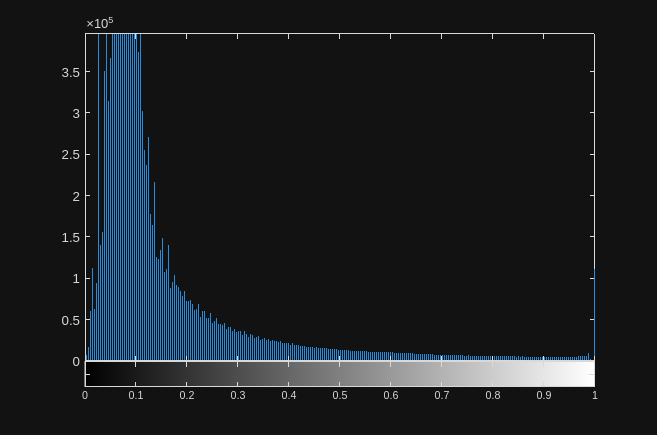

% Adaptive histogram
imgHSV = rgb2hsv(img);
val = imgHSV(:, :, 3);
val = adapthisteq(val);
imhist(val);

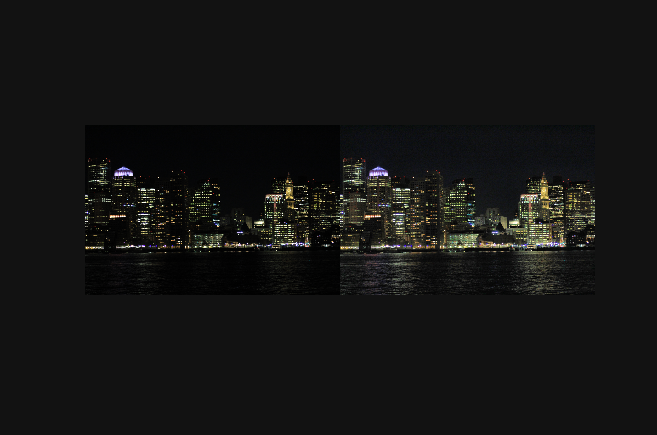

imgHSV(:, :, 3) = val;
imgAdapted = im2uint8(hsv2rgb(imgHSV));
montage({img, imgAdapted});